# Supplement 5: Simulation of NMR spectra at zero and ultra-low field - Case of XAn spin system

Supplementary material to "Simulation of NMR spectra at zero- and ultra-low field from A to Z – a tribute to Prof. Konstantin L’vovich Ivanov" [https://doi.org/10.5194/mr-2022-18](https://doi.org/10.5194/mr-2022-18) 

*Q. Stern and K. Sheberstov*

This script shows how to simulate ZULF spectra for an XAn spin system. It was used to generate Figure 6 of the paper.

Figure path and plot options

clear all
FigurePath='C:\Users\quent\Documents\Projects\Tutorial paper on ZULF\Figures\';
c1=[0    0.4470    0.7410];
c2=[1 1 1]*0.5;
lw=1;

## General paramaters and operators

#### Spin system paramaters

JIS=140;            % J-coupling between I and S in Hz
JSS=10;             % J-coupling between S spins in Hz
gI= 67.262e6;       % Gyromagnetic ration of spin I (13C) in rad.s-1.T-1
gS=276.513e6;       % Gyromagnetic ration of spin S (1H) in rad.s-1.T-1

#### Experimental conditions

Bpol=2;             % Field for prepolarization in T
T=298;              % Temperature of prepolarization in K
Bx=0.5e-6;          % Magnetic field along x for ultra-low field experiments in T
Bpulse=50e-6;       % Magnetic field along x during DC pulses in T
NA=6.02e23;         % Avogadro's number in mol-1
C=27;               % Molecule concentration in mol.L-1
V=100e-6;           % Sample volume in L
r=0.01;             % Distance between the center of the sample and the center of the detector in m

#### Physical constants

hbar=1.05457e-34;   % Reduced Planck constant in J.s
kB=1.3806485e-23;   % Boltzmann constant J.K-1
mu0=4*pi*1e-7;      % Permeability of free space dived in T.m.A-1 

#### Parameters for propagation

taq=5;              % Propagation/acquisition time in s
K=2^13;             % Number of points in the FID
L=2^16;             % Number of points in the FID with zero filling
T2=1;               % Coherence time constant in s
dt=taq/K;           % Time interval for propagation in s
t=(0:K-1)'/K*taq;   % Time axis in s

#### Frequency axis

f=(K-1)/taq;        % Sampling frequency in Hz
nu=(0:L/2-1)/L*f;   % Frequency axis in Hz

#### Initial polarization

Polarization of spin I at equilibrium in the prepolarizing magnet calculated using Boltzman distribution

PI=tanh(hbar*Bpol*gI/kB/T/2);

Polarization of spin S at equilibrium in the prepolarizing magnet calculated using Boltzman distribution

PS=tanh(hbar*Bpol*gS/kB/T/2);

#### Cells to store the FID and spectra

Maximum number of X spins

N=5;

Cells to stores the time domain signals

TDS_ZF=cell(N,1);
TDS_ULF=cell(N,1);

Cells to store the frequency domain signals

FDS_ZF=cell(N,1);
FDS_ULF=cell(N,1);

#### Basis operators in single-spin Hilbert space

Pauli matrices

e =[1 0;  0 1];
sx=[0 1;  1 0];
sy=[0 -1i;1i 0];
sz=[1 0;  0 -1];

Angular momentum operators in single spin space

Ix_=sx/2; 
Iy_=sy/2;
Iz_=sz/2;
E=eye(2);

Number of molecules in the sample

N_molecules=NA*C*V;

## Loops over the number of X spins

parfor n=1:N
    % Total number of spins of the AXn spins system
    m=1+n;
    
    % Constructs the operators for m-dimensional Hilbert space
    Ix=cell(m,1);
    Iy=cell(m,1);
    Iz=cell(m,1);
    for i=1:m
        Ix{i}=1; Iy{i}=1; Iz{i}=1;
        for j=1:m
            if i==j
                Ix{i}=kron(Ix{i},Ix_);
                Iy{i}=kron(Iy{i},Iy_);
                Iz{i}=kron(Iz{i},Iz_);
            else
                Ix{i}=kron(Ix{i},E);
                Iy{i}=kron(Iy{i},E);
                Iz{i}=kron(Iz{i},E);
            end
        end
    end
    
    % Constructs the Zeeman Hamiltonian
    HZ=@(Bx, By, Bz) -gI*(Bx*Ix{1}+By*Iy{1}+Bz*Iz{1});
    for i=2:m
        HZ=@(Bx, By, Bz) HZ(Bx, By, Bz) -gS*(Bx*Ix{i}+By*Iy{i}+Bz*Iz{i});
    end    
    
    % Constructs the J-Hamiltonian
    HJ=zeros(2^m);
    for i=2:m
        % AX couplings
        HJ=HJ +2*pi*JIS*(Ix{1}*Ix{i}+Iy{1}*Iy{i}+Iz{1}*Iz{i});
        
        % XX couplings
        for j=i+1:m
            HJ=HJ +2*pi*JSS*(Ix{i}*Ix{j}+Iy{i}*Iy{j}+Iz{i}*Iz{j});
        end
    end
    
    %  Constructs the density matrix
    rho0=eye(2)/2+PI*Iz_;
    for i=2:m
        rho0=kron(rho0,eye(2)/2+PS*Iz_);
    end  

    % Removes the identity
    rho0=rho0-eye(2^m)/2^m;
    
    % Constructs the propagators at zero and ultra-low field
    U_ZF =expm(-1i*dt*HJ);
    U_ULF=expm(-1i*dt*(HJ+HZ(Bx,0,0))); 
    
    % Constructs the observable operator in pT
    O=gI*Iz{1};
    for i=2:m
        O=O+gS*Iz{i};
    end
    
    % Conversion to pT
    O=N_molecules*hbar*1e12*mu0/2/pi/r^3*O;
    
    % Creates empty vectors to store the time domain signals
    TDS_ZF{n}= zeros(length(t),1);
    TDS_ULF{n}=zeros(length(t),1);
    
    % Propagation loop for the ZF case
    % Initialization of the density matrix
    rho=rho0;
    for k=1:K
        % Computes the expectation value of the field along z
        TDS_ZF{n}(k)=TDS_ZF{n}(k)+real(trace(O*rho));
        
        % Propagates during dt
        rho=U_ZF*rho*U_ZF';
    end
    
    % Propagation loop for the ULF case
    rho=rho0;
    for k=1:K
        % Computes the expectation value of the field along z
        TDS_ULF{n}(k)=TDS_ULF{n}(k)+real(trace(O*rho));
        
        % Propagates during dt
        rho=U_ULF*rho*U_ULF';
    end
    
    % Apodization function - line broadening
    TDS_ZF{n} =TDS_ZF{n} .*exp(-t/T2);
    TDS_ULF{n}=TDS_ULF{n}.*exp(-t/T2);
    
    % Fourier transform
    FDS_ZF{n}  = FourierTransform(TDS_ZF{n},L);
    FDS_ULF{n} = FourierTransform(TDS_ULF{n},L);
end

## Plots the results

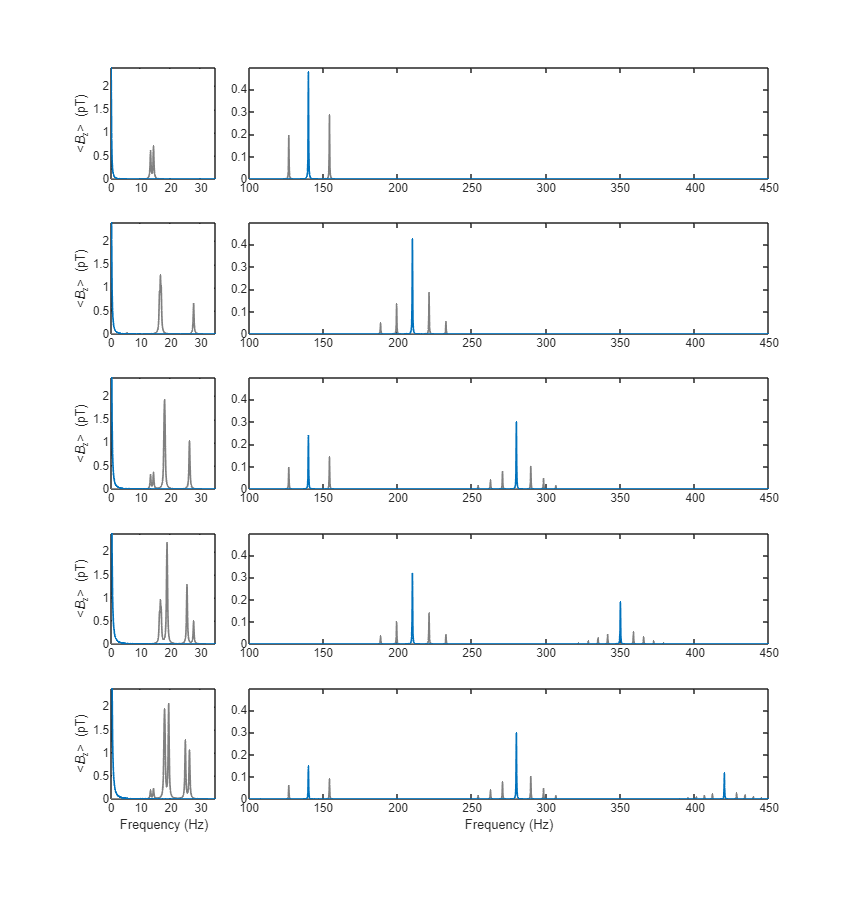

figure("Units","centimeters","Position",[0 0 18 19])
for i=1:N
    subplot(N,5,1+(i-1)*5)
    plot(nu, real(FDS_ULF{i}),'linewidth',lw,'color',c2), hold on
    plot(nu, real(FDS_ZF{i}), 'linewidth',lw,'color',c1), hold off
    xlim([0 35]), ylim([0 2.4])
    ylabel('<{\itB}_z> (pT)')
    xticks([0 10 20 30])
    set(gca,'fontsize',7)
    
    if i==N
        xlabel('Frequency (Hz)')
    end
    
    subplot(N,5,(i-1)*5+(2:5))
    plot(nu, real(FDS_ULF{i}),'linewidth',lw,'color',c2), hold on
    plot(nu, real(FDS_ZF{i}), 'linewidth',lw,'color',c1), hold off
    xlim([100 450]), ylim([0 0.5])
    set(gca,'fontsize',7)
    
    if i==N
        xlabel('Frequency (Hz)')
    end
end

exportgraphics(gcf,fullfile(FigurePath, 'XAn_system_spectra.pdf'),'ContentType','vector')

## Functions

function S=FourierTransform(I,N)
    % Converts to column vector
    I=I(:);
    
    % Window function to avoid baseline shift
    I=[I(1); 2*I(2:end-1); I(end)];
    
    % Fourier transform
    S = real(fft(I,N))/N;
    
    % Remove negative frequencies
    S=2*S(1:N/2);
end